Parte 2

clc
clear all

n=[0,1,2,3]

n =      0     1     2     3


x=cos(pi*n/2)

x =     1.0000    0.0000   -1.0000   -0.0000


N=length(x);
X = zeros(1, N);
for k=1:N
    for n=1:N
        X(k)=X(k)+x(n)*exp((-2*pi*j/N)*((n-1)*(k-1)));
    end
end
k=0:N-1;
disp('Resultado:');

Resultado:


disp(X);

  -0.0000 + 0.0000i   2.0000 - 0.0000i   0.0000 - 0.0000i   2.0000 + 0.0000i



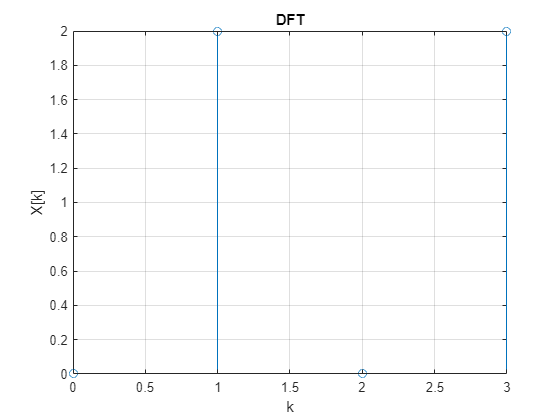

abs(X(k+1));
figure(1);
stem(k,abs(X(k+1)));
grid;
xlabel('k');
ylabel('X[k]');
title('DFT');
hold off;

%Comprobando con la funcion directa en matlab
fft(x)

ans =   -0.0000 + 0.0000i   2.0000 - 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i


PARTE 3:

a) Para x=(0,2)

xa=[0,2];
N=length(xa);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xa(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   1.0000 + 0.0000i  -1.0000 + 0.0000i



b) Para x=(0,-2j,0,2j)

xb=[0,-2j,0,2j];
N=length(xb);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xb(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i  -1.0000 + 0.0000i



c) Para x=(0, 4, 0, 0, 4)

xc=[0,4,0,0,4];
N=length(xc);
x = zeros(1, N);
for n=1:N
    for k=1:N
        x(n)=x(n)+xc(k)*exp((2*pi*1i*(k-1)*(n-1))/N);
    end
end
n=0:N-1;
y=1/N*x(n+1);
disp(y);

   1.6000 + 0.0000i   0.4944 - 0.0000i  -1.2944 + 0.0000i  -1.2944 + 0.0000i   0.4944 - 0.0000i

